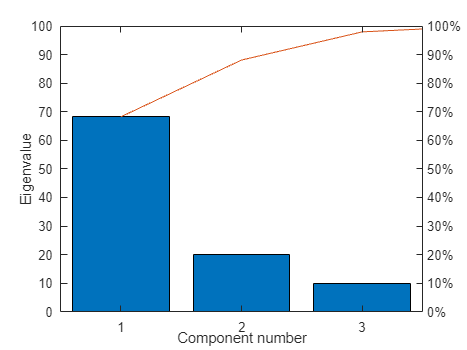

%主成分分析（第三套方法）
clear                                       %清理内存
% load C:\MATLAB7\work\cities2003
cities2003   %调出保存的数据
X=zscore(data);                            %原始数据集合集体标准化
[n,m]=size(data);                          %计算矩阵的行数和列数

% [E,score,eigv,T]=princomp(X);              %调用主成分分析程序 princomp
[E,score,eigv,T]=pca(X);              %调用主成分分析程序
per=100*eigv/sum(eigv);                    %计算方差贡献百分比
Cum=cumsum(per);                           %计算方差贡献累计百分比
figure(1);                                 %创建第一个图形窗口
pareto(per);                               %将贡献率绘制成直方图
xlabel('Component number');                %横轴标签(成分数)
ylabel('Eigenvalue');                      %纵轴标签(特征值)

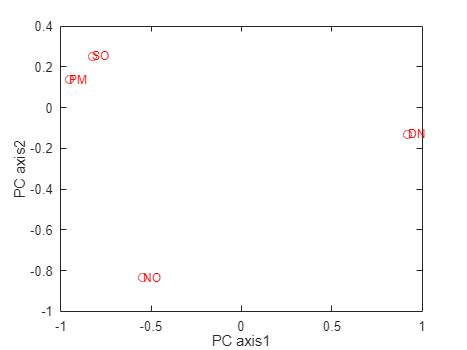

lambda=diag(eigv);                         %用特征值构成对角阵
C=sqrtm(lambda);                           %将对角矩阵对角线元素化为平方根
A=-E*C;                                    %计算载荷矩阵(转换为负值)
Co1=A(:,1).^2;                             %提取1个主成分的公因子方差
Co2=Co1+A(:,2).^2;                         %提取2个主成分的公因子方差
Co3=Co2+A(:,3).^2;                         %提取3个主成分的公因子方差
Co4=Co3+A(:,4).^2;                         %提取4个主成分的公因子方差
Comm=[Co1,Co2,Co3,Co4];                    %将4个公因子方差向量合并为一个矩阵
H=A(:,1:2);                                %提取第一、第二主成分的载荷
stdr=std(score);                           %计算主成分得分的标准差
F=-score./stdr(ones(n,1),:);               %主成分得分集体标准化(转换为负值)
Fe=F(:,1:2);                               %提取第一、第二主成分的得分
figure(2);                                 %创建第二个图形窗口
plot(H(:,1),H(:,2),'rO');                  %打印二维载荷散点图
xlabel('PC axis1')                         %横轴标签(主轴1)
ylabel('PC axis2')                         %纵轴标签(主轴2)
text(H(:,1),H(:,2),varname,'FontSize',9,'Color','r');  %静态标注变量（原为交互式gname）

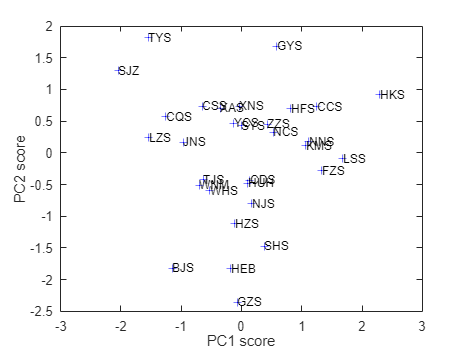

figure(3);                                 %创建第三个图形窗口
plot(Fe(:,1),Fe(:,2),'b+');                %打印二维主成分散点图
xlabel('PC1 score')                        %横轴标签(第一主成分得分)
ylabel('PC2 score')                        %纵轴标签(第二主成分得分)
text(Fe(:,1),Fe(:,2),casename,'FontSize',9);  %静态标注城市（原为交互式gname）

R=cov(X);                                  %计算并输出协方差矩阵
Rp=H*H';                                   %计算再生相关矩阵
Re=R-Rp;                                   %计算相关矩阵的残差矩阵
%残差分析
[Resi,Reco]=pcares(data,4);                %计算残差矩阵和重构矩阵
% Sumsq=sumsqr(Res);                         %计算残差平方和
Sumsq=sumsqr(Resi);

%从协方差矩阵出发
% load C:\MATLAB7\work\cities2003              %调出保存的数据
mv=mean(data);                               %计算各变量的均值
st=std(data);                                %计算各变量的标准差
[n,m]=size(data);                            %计算矩阵的函数和列数
X=(data-mv(ones(n,1),:))./st(ones(n,1),:);   %原始数据集体标准化
% V=data-mv(ones(n,1),:);                      %原始数据中心化
Y=data-mv(ones(n,1),:);                      %原始数据中心化
R=Y'*Y/(n-1);                                %计算原始数据的协方差
R=cov(X);                                    %计算相关系数矩阵
[E, eigv, expl]=pcacov(R);                   %从协方差矩阵出发

%绘制综合得分与T统计量的关系图
figure;

TScore=[-3.5172	-2.3298	-2.2177	-2.2147	-1.9264	-1.6067	-1.5683	-1.4484	-1.4196	-1.4027	-1.1842	-0.9379	-0.6806	-0.4274	-0.4216	-0.2609	-0.1601	0.0423	0.1993	0.3765	0.5967	1.1034	1.1589	1.8626	1.9415	1.9735	1.9992	2.464	2.69	2.7117	4.6045];
T=[6.5426	6.7736	13.9607	5.0502	2.7991	2.5131	5.1351	3.2219	1.2612	1.4518	1.04	9.5635	2.2586	0.893	1.6468	0.3455	0.3404	1.0211	0.3453	0.4826	1.7876	0.6665	0.9099	3.7042	4.9977	4.0072	5.2497	7.7893	5.1263	15.7572];
plot(TScore,T, 'ro');

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlabel('TScore');
ylabel('T');
hold on
b=polyfit(TScore, T,2);
f=b(1)*TScore.^2+b(2)*TScore+b(3);
plot(TScore,f,'b-');
hold off